### Performing FFT and Inverse FFT.

%Defining Parameters
L = 2*pi; % sampling points on circle
N = 64; 
dx = L/N;
x = (0:N-1)*dx; 

%Periodic Function
u=exp(-sin(x/2).^2)

u =     1.0000    0.9976    0.9904    0.9787    0.9627    0.9427    0.9192    0.8927    0.8638    0.8329    0.8007    0.7677    0.7344    0.7013    0.6687    0.6370    0.6065    0.5775    0.5502    0.5246    0.5009    0.4792    0.4594    0.4417    0.4259    0.4121    0.4002    0.3903    0.3822    0.3759    0.3714    0.3688    0.3679    0.3688    0.3714    0.3759    0.3822    0.3903    0.4002    0.4121    0.4259    0.4417    0.4594    0.4792    0.5009    0.5246    0.5502    0.5775    0.6065    0.6370



%Fourier Transform
u_hat=fft(u);

Now, we want to decide a correct wavenumber, if not the spectral method will become nonsense

Logic: 

1) Manually map the discrete indices to physical frequencies

2) Hence, we want to choose the smallest possible non-zero frequency(fundamental). Here is should be 2*pi/L. 

3)  On a grid of "N" points, the computer can only "see" a certain maximum speed (the **Nyquist frequency**). Any wave faster than that "aliases" and looks like a slower wave moving in the opposite direction.  (take 1 to 8 index) 

 ***

Why the Nyquist freq is forced as zero? Technically, it should be 4. But, k=4 is the excat limit of what the grid can solve. As in, for the middle, N/2 and -N/2 are the same, which is not the case for positive modes, i.e. for a positive mode, say 1, we have -1 which is a negative mode, and both are distinct. But, 4 and -4, in the circle are the same-the phase information is lost! The positive mode(say 1) and its conjugate(-1) when combined together, give a real entity. But, such is not the case for N/2. Hence, we force it to be 0, so that it doesnt become a complex exponential.

(Remark: When we differentiate, we will get an ik component. Hence, we get purely imaginary qty. while doing the inverse FT, it has no conjugate partner to cancel the imaginary part.)  

% 2. Define the correct Wavenumber vector (k)
% This matches the order of fft(u)
k = (2*pi/L) * [0:N/2-1, 0, -N/2+1:-1]';
% []' the quotation mark is for transposing 

% 3. Inverse Transform to get back to physical space
u_recovered = real(ifft(u_hat)); 

We obtained our matrices. Now, to visualize our result, we will plot the respective functions:

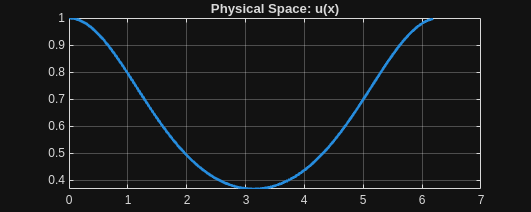

% --- VISUALIZATION ---
figure('Position', [100, 100, 1000, 400]);

% Plot 1: Physical Space (The "Function")
figure(1); 
plot(x, u, 'LineWidth', 2);
title('Physical Space: u(x)');
grid on;

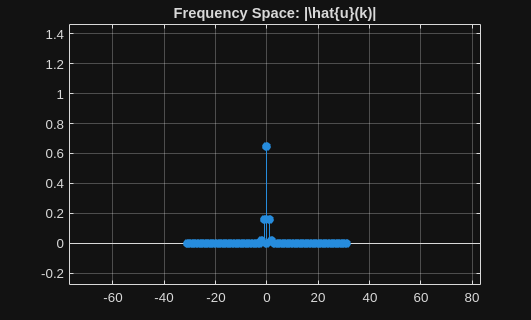


% Plot 2: Fourier Space (The "Matrix/Coefficients")
% We use fftshift to put 0 in the middle for easier viewing
figure(2); 
stem(fftshift(k), abs(fftshift(u_hat))/N, 'filled');
title('Frequency Space: |\hat{u}(k)|', 'Interpreter', 'none');
grid on;